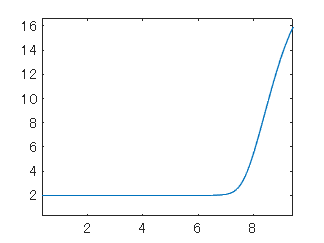

m=1;
g=9.81;
r=2;
c=1;
k1=5;
k2=k1+sqrt(m*g/c);
ue=sqrt(m*g/c)*r;
time=[0 10];

y0=[r;0];
f=@(t,y)[y(2); m*g-c*(-k1*y(1)+k2*r).^2/y(1).^2];
[t,y]=ode45(f,time,y0);
plot(t,y(:,1));

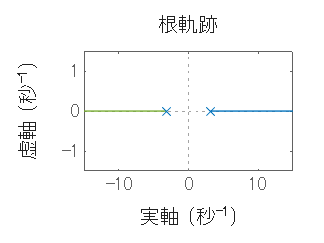

A=[0 1;c/m*2*(ue.^2/r.^3) 0];
B=[0; -c/m*2*ue/r.^2];
C=[1 0];
D=0;
sys=ss(A,B,C,D);

rlocus(sys);